# Illustrate sensor aliasing using a monochrome sensor

When the ability of a lens to render high spatial frequencies exceeds the sampling rate of the sensor, the outputs from the sensor can be incorrectly interpreted.  These are called aliased patterns. These patterns appear to be low frequency sensor responses even though the original image is high frequency. The unwanted co caused by the high frequency patterns in the original image but the under-sampling makes them appear to be low frequency images.

To protect against aliasing, you can use a lens that does not pass the high frequency terms. The simple case - of a monochrome sensor - is illustrated first.

There are special considerations for aliasing when we use a color filter array. These are illustrated here for a sensor with a color filter array.

**See also:**  hwSensorAliasing, s_sensorAliasing

ieInit

## Set up a high frequency harmonic

fov = 1;
hParams = harmonicP;
hParams.freq = 8;
hParams.row = 128; hParams.col = 256;
scene = sceneCreate('harmonic',hParams);
scene = sceneSet(scene,'fov',fov);
sceneWindow(scene);

% Set up a high quality lens
oi = oiCreate('diffraction limited');
oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);
oiWindow(oi);

## We use a small (1 um) pixel size and see the scene come through correctly

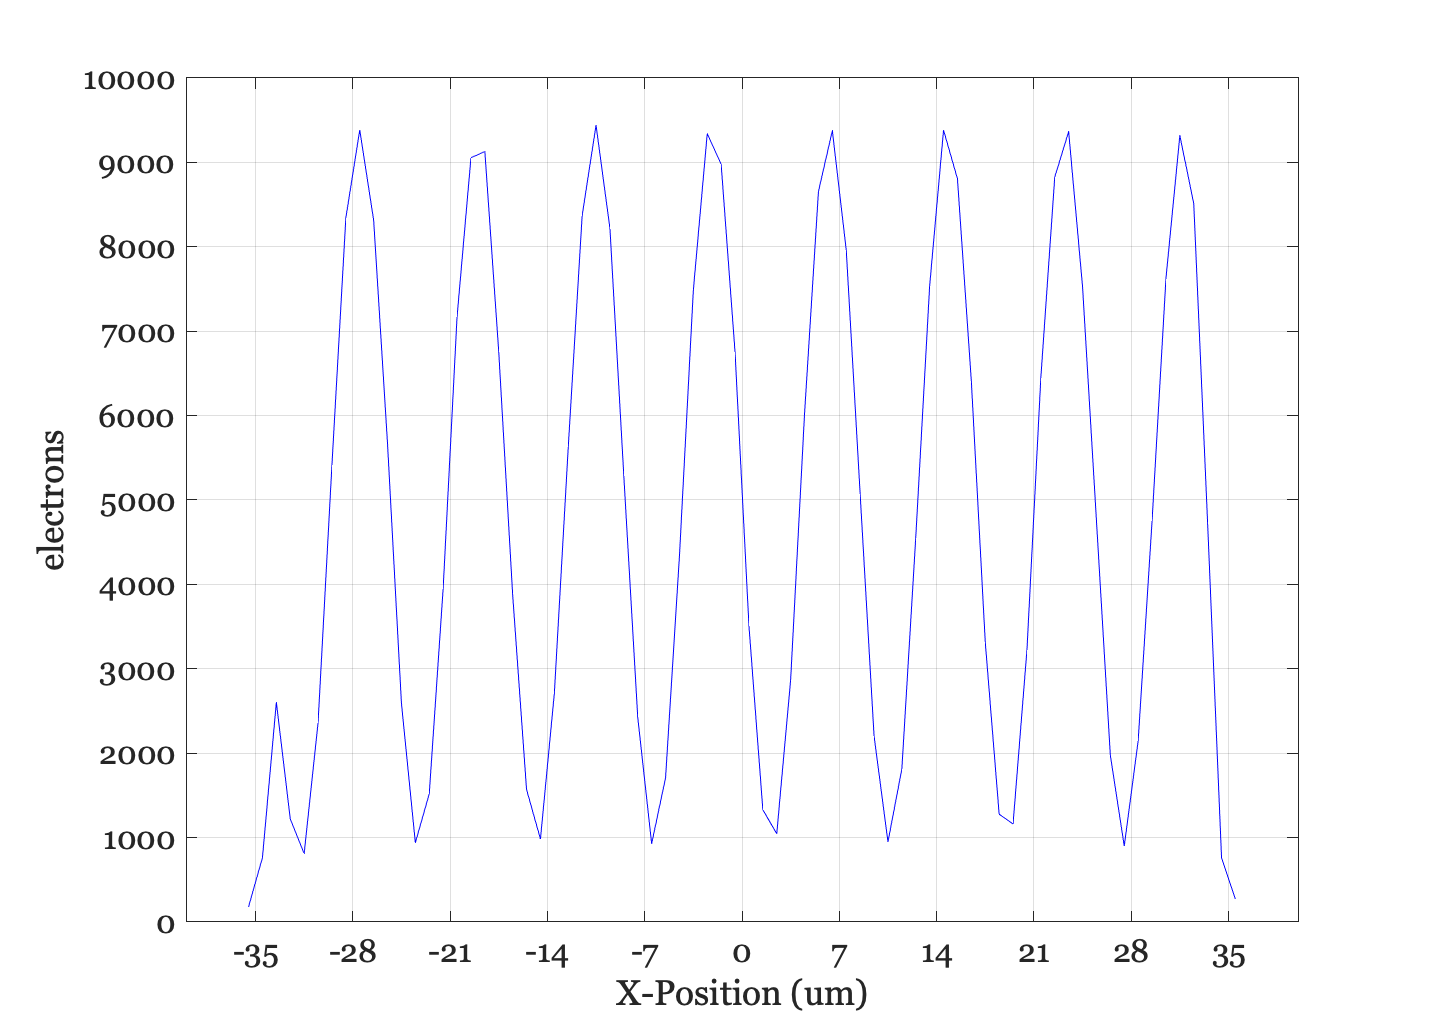

sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,3*fov,oi);

% Set a 2 micron pixel
sensor = sensorSet(sensor,'pixel size constant fill factor',1e-6);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Use a bigger pixel (10 um)

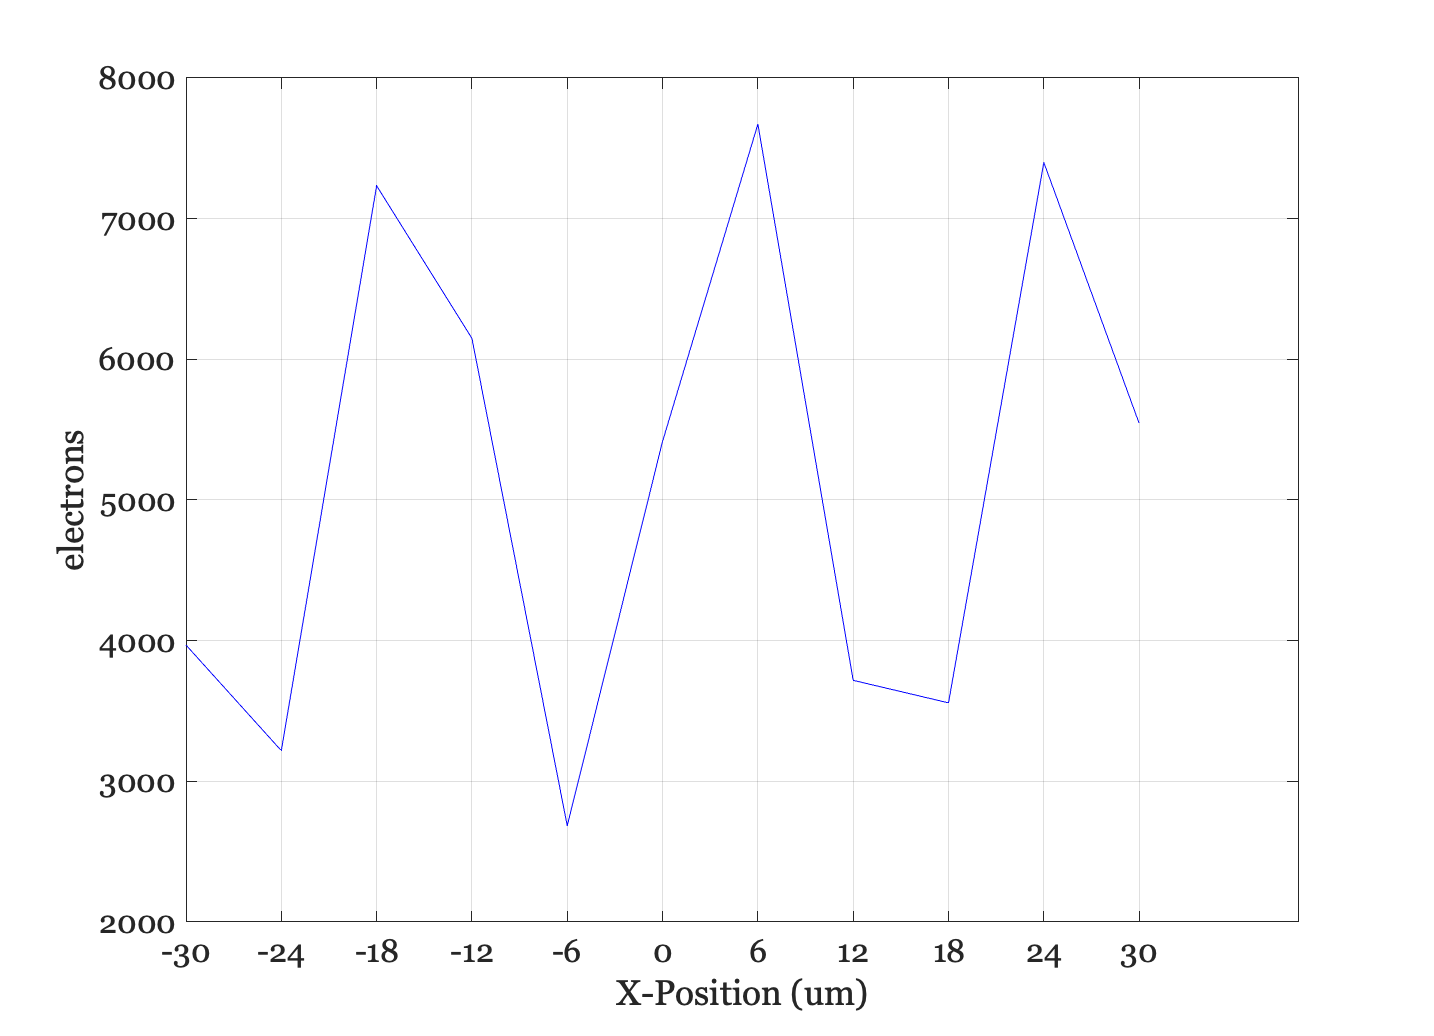

% Now, notice the aliased signal on the right.  The scene and oi are high
% spatial frequency, but the sensor capture appears to be low spatial
% frequency.
sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Now, reduce aliasing by using a blurry lens

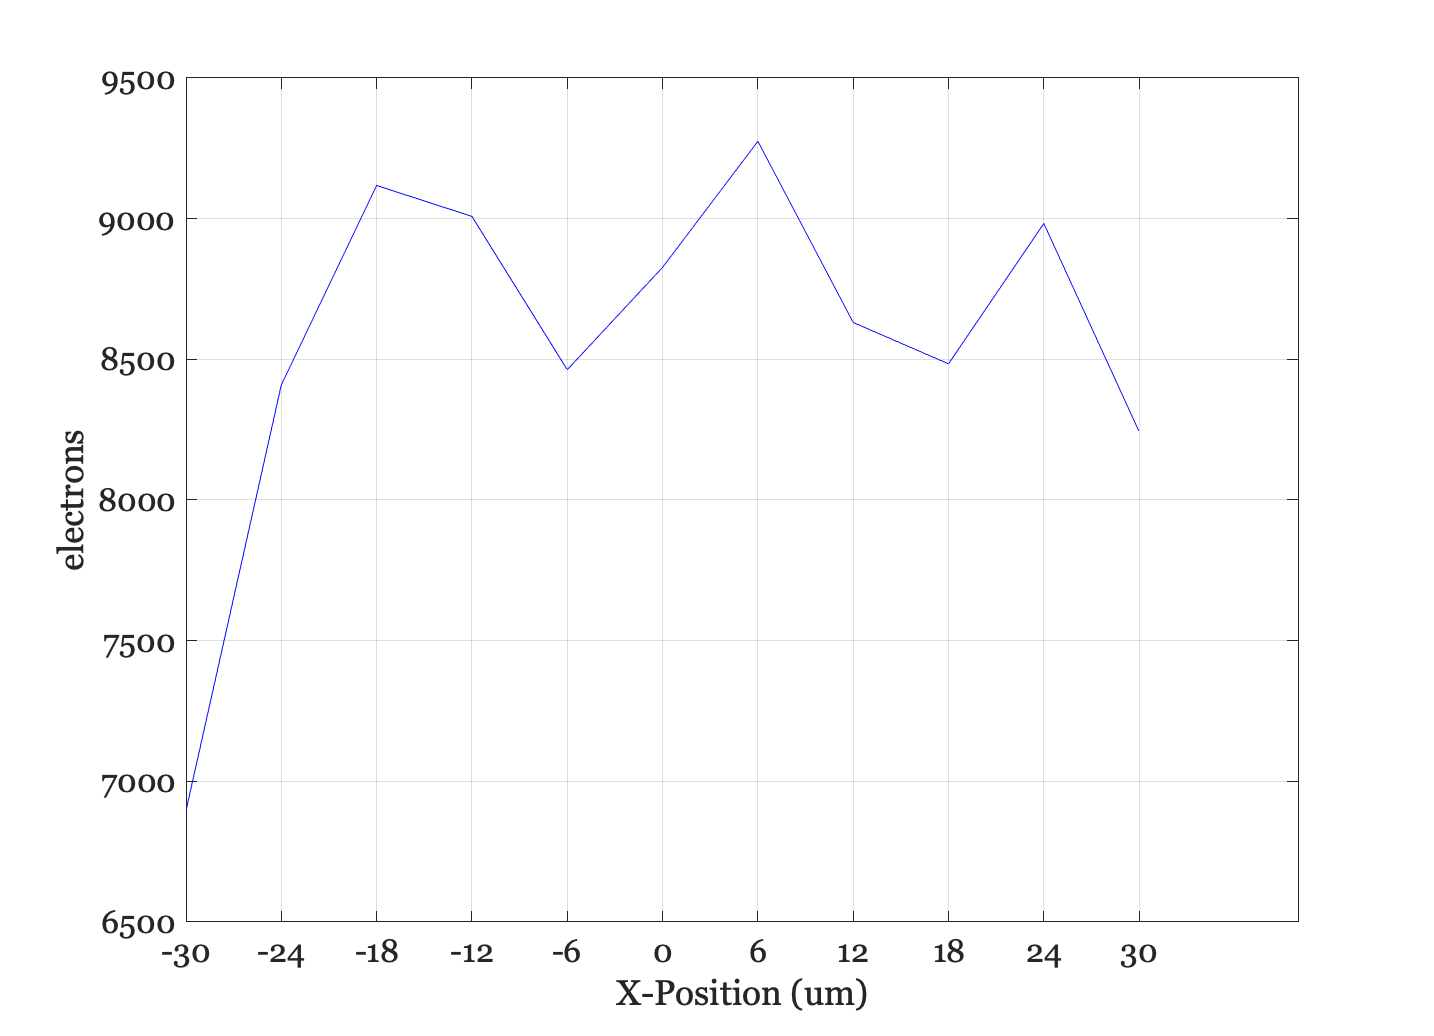

oi = oiSet(oi,'optics fnumber', 14);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Next, what happens with a CFA?

oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);

sensor = sensorCreate;
sensor = sensorSet(sensor,'pixel size constant fill factor',1e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

## Next, what happens with a CFA?

sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,2*fov,oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

## Here is higher resolution target that illustrates the problem

scene = sceneCreate('freqorient',[512 512]);
oi = oiCompute(oi,scene);
oiWindow(oi);
sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,sceneGet(scene,'fov'),oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);
ip = ipCreate;
ip = ipCompute(ip,sensor);
ipWindow(ip);
